**Note - Program the device with the Bitfile generated from Vivado project. Follow the instructions in the tutorial**

© Copyright 2025 The MathWorks, Inc.

% Move Slider to generate error condition. Pulse is not detected 
tshldErr = 0 

tshldErr = 0

% Define Register Addresses here
REG_PD_BASE = 0x43c00000;
REG_PD_TH = REG_PD_BASE + 0x00100 ; % Pulsedetect Threshold register
REG_PD_OLEN = REG_PD_BASE + 0x00104 ; % Pulsedetect Output Length
% AXIS Stream FIFO
REG_AXISF_Base = 0x43C10000;
REG_AXSIF_IS = REG_AXISF_Base;
REG_AXISF_TDFR = REG_AXISF_Base + 0x000008; %Transmit Data FIFO Reset (TDFR) Write
REG_AXISF_TDFV = REG_AXISF_Base + 0x00000C; %Transmit Data FIFO Vacancy (TDFV) Read
REG_AXISF_TDFD = REG_AXISF_Base + 0x000010; %Transmit Data FIFO 32-bit Wide Data Write Port 
REG_AXISF_TLR  = REG_AXISF_Base + 0x000014; %Transmit Length Register (TLR)
REG_AXISF_RDFR = REG_AXISF_Base + 0x000018; %Receive Data FIFO reset (RDFR)
REG_AXISF_RDFO  = REG_AXISF_Base + 0x00001c; %Receive Data FIFO Occupancy(RDFO)
REG_AXISF_RDFD  = REG_AXISF_Base + 0x000020; %Receive Data FIFO 32-bit Wide Data Read Port 
REG_AXISF_RLR   = REG_AXISF_Base + 0x000024; %Receive Length Register
REG_AXISF_SRR   = REG_AXISF_Base + 0x000028; %AXI4-Stream Reset (SRR)

%Simple test block
 h = aximanager('Xilinx');
 writememory(h,REG_PD_TH,fi(0.2,0,18,11));
 rdata = readmemory(h,REG_PD_TH,1,'OutputDataType',numerictype(0,18,11));
 disp(rdata);

    0.2002

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Unsigned
            WordLength: 18
        FractionLength: 11


 release(h);

%First write to Transmit Data Register
% Length of test signal
testSignalLength = 1024;
out_len = 256; %Output Pulse length

% Test signal noise scale
noiseScale = 1e-2;

% Location of pulse in test signal
PulseLoc = 300;
testSignal = generate_test_signal(testSignalLength,noiseScale,PulseLoc);
fi_testSignal = real(fi(testSignal,1,16,14));

h = aximanager('Xilinx');

%===============
% PULSE DETECT
% Write to Threshold Register

th_val = 0;
if tshldErr == 1  % Threshold Programming error
    th_val = 2;
else 
    th_val = 0.2;  
end



writememory(h,REG_PD_TH,fi(th_val,0,18,11));


% Write to output length Register
writememory(h,REG_PD_OLEN,out_len);

%================
% AXIS FIFO

% Reset AXI4 Stream 
writememory(h,REG_AXISF_SRR,0xa5);

%Reset the Transmit FIFO
writememory(h,REG_AXISF_TDFR,0xa5);
writememory(h,REG_AXISF_TDFR,0x0);

%Reset the RX FIFO
writememory(h,REG_AXISF_RDFR,0xa5);
writememory(h,REG_AXISF_RDFR,0x0);

% Clear Interrupt Status
writememory(h,REG_AXSIF_IS,0xFFFFFFFF);

% Write Pulse to FIFO
writememory(h,REG_AXISF_TDFD,fi_testSignal,'BurstType','Fixed');


%Write Pulse Length to FIFO
writememory(h,REG_AXISF_TLR,testSignalLength*4); % Number of bytes

% Read Pulse length
rdata = readmemory(h,REG_AXISF_RLR,1);
fprintf("\n Number of Bytes in Receive FIFO = %d \n",int32(rdata));


 Number of Bytes in Receive FIFO = 1024 


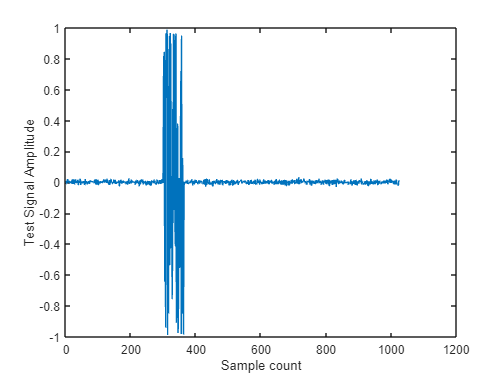


% Get the Received Pulse
pulse_rx = readmemory(h, REG_AXISF_RDFD,out_len,'BurstType','Fixed','OutputDataType',numerictype(1,16,14));

plot(real(testSignal))
xlabel('Sample count')
ylabel('Test Signal Amplitude')

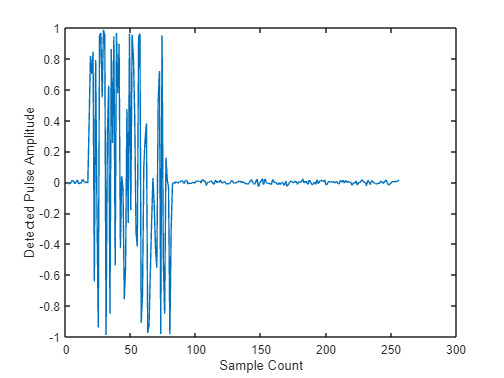

plot(pulse_rx);
xlabel('Sample Count')
ylabel('Detected Pulse Amplitude')

release(h);

th_val

th_val = 0.2000